# Merging Simulink Models Automatically in Git

[ ](https://matlab.mathworks.com/open/github/v1?repo=simulink/blog&project=2025_06_30_Git_Merge/Git_Merge.prj)

This post is targeted at users developing Simulink models under [Git](https://en.wikipedia.org/wiki/Git) source control, but who are not necessarily using the [MATLAB source control integration](https://www.mathworks.com/help/matlab/matlab_prog/about-mathworks-source-control-integration.html).

I personally work in MATLAB and Simulink all day, so the [MATLAB source control integration](https://www.mathworks.com/help/matlab/matlab_prog/about-mathworks-source-control-integration.html) usually does the job for me. However, I realize that many Simulink users deal with projects including multiple software and artifacts, and prefer to use Git command-line or  a dedicated Git client to manage all that. Examples I see regularly are [GitHub Desktop](https://desktop.github.com/), [GitKraken](https://www.gitkraken.com/) and [Sourcetree](https://www.sourcetreeapp.com/).

If that's your case, keep reading. This post goes step-by-step through the instructions provided in this documentation page: [Automatically Merge Models Locally and in CI Pipeline - MATLAB & Simulink](https://www.mathworks.com/help/simulink/ug/enable-matlab-automerge.html)

## The Problem

Let's use a very simple example. I have a folder with a Simulink model

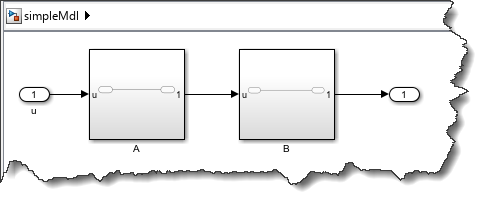

I initialize the folder for Git, add and commit the model:

I then create a sparate branch where I make a modification in Subsystem A and commit the changes.

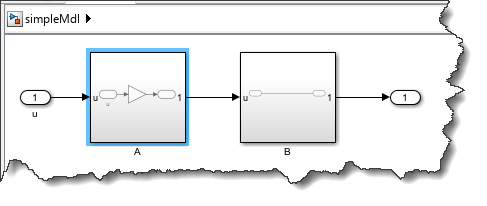

At the same time, a second user create another branch and makes modifications to subsystem B

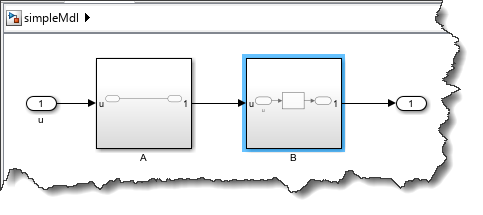

In the meantime, unrelated changes have been committed to the Master branch, so I have a situation like this:

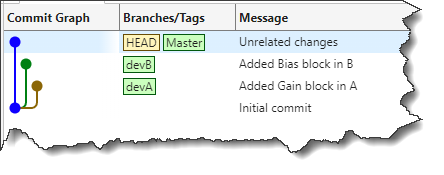

Now I want to merge branches devA and devB into the master branch

At this point, I will get an error that looks like this:

As the warning says, since Simulink models are binary files, by default Git cannot merge automatically.

Let's see how to fix that!

## Configure the global .gitconfig

For many releases now, MathWorks ship with Simulink diff and merge tools that can be registered in Git. Those need to be registered in your [global `.gitconfig`](https://git-scm.com/book/en/v2/Customizing-Git-Git-Configuration) file.

To make it easy, you can simply type this line in MATLAB:

comparisons.ExternalSCMLink.setupGitConfig();

merge.mlAutoMerge.driver is stored in "C:\Users\grouleau\.gitconfig":
    "L:/MATLAB/R2025a/bin/win64/mlAutoMerge.bat" %O %A %B %A.
mergetool.mlMerge.cmd is stored in "C:\Users\grouleau\.gitconfig":
    "L:/MATLAB/R2025a/bin/win64/mlMerge.bat" $BASE $LOCAL $REMOTE $MERGED.
difftool.mlDiff.cmd is stored in "C:\Users\grouleau\.gitconfig":
    "L:/MATLAB/R2025a/bin/win64/mlDiff.bat" $LOCAL $REMOTE.


This will automatically add the required lines to your global `.gitconfig` file.

## Configure your repository

The next step is to add a [`.gitattributes`](https://git-scm.com/docs/gitattributes) file to your repository to tell Git that SLX Simulink models are binary files and can be merged using the previously registered tools.

Note that when using the [MATLAB source control integration](https://www.mathworks.com/help/matlab/matlab_prog/about-mathworks-source-control-integration.html), this `.gitattributes` file is automatically generated and added to your repository. If you prefer managing your source control business outside of MATLAB, you need to do it yourself.

## Let's Merge!

With that setup, Git will now be able to automatically merge Simulink models. Here is a screenshot where I use Git Bash to do the merge that had previously failed:

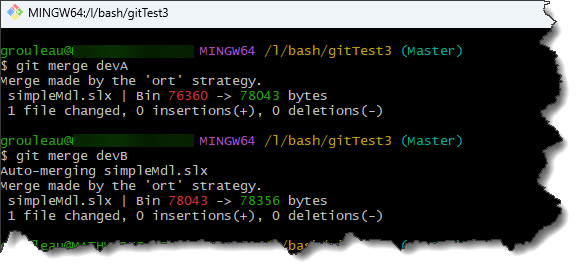

I can look at the model to confirm that all the changes have been merged properly.

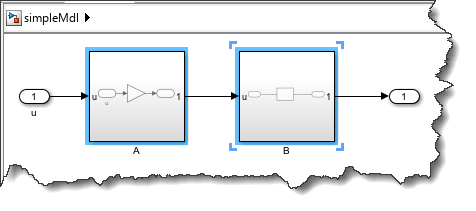

## What if there is a conflict or we cannot auto-merge?

If you took the time to read [Automatically Merge Models Locally and in CI Pipeline - MATLAB & Simulink](https://www.mathworks.com/help/simulink/ug/enable-matlab-automerge.html), you hopefully noticed this note:

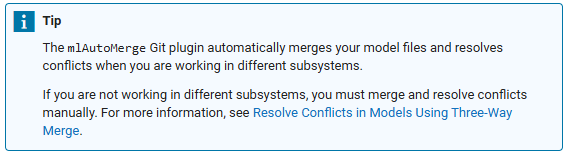

For example, let's say I have a library where a different block has been added at the top level in two branches:

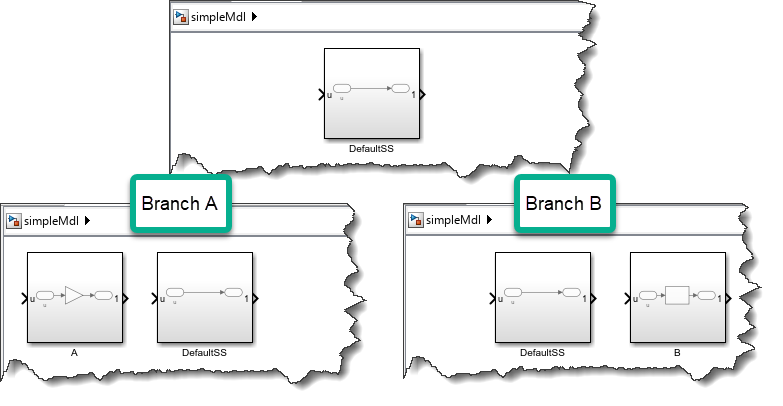

The auto-merge will fail when trying to merge branch B after having merged branch A.

In that case, you will need to launch MATLAB. In R2025a, you can use the new Source Control panel and select View Conflicts:

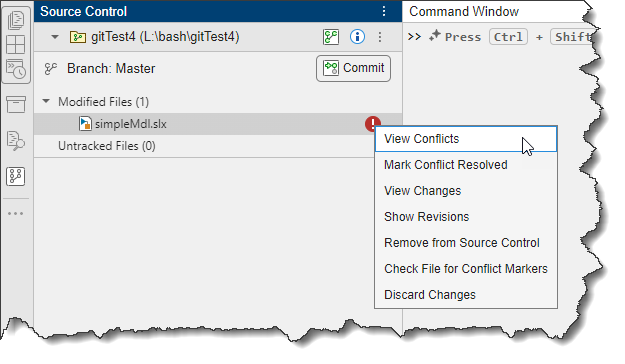

This will launch the [Three-Way Merge tool](https://www.mathworks.com/help/simulink/slref/simulinkthreewaymergetool.html). In this simple case, the tool will be able to automatically do the merge, so all you have to do is click **Apply & Close**.

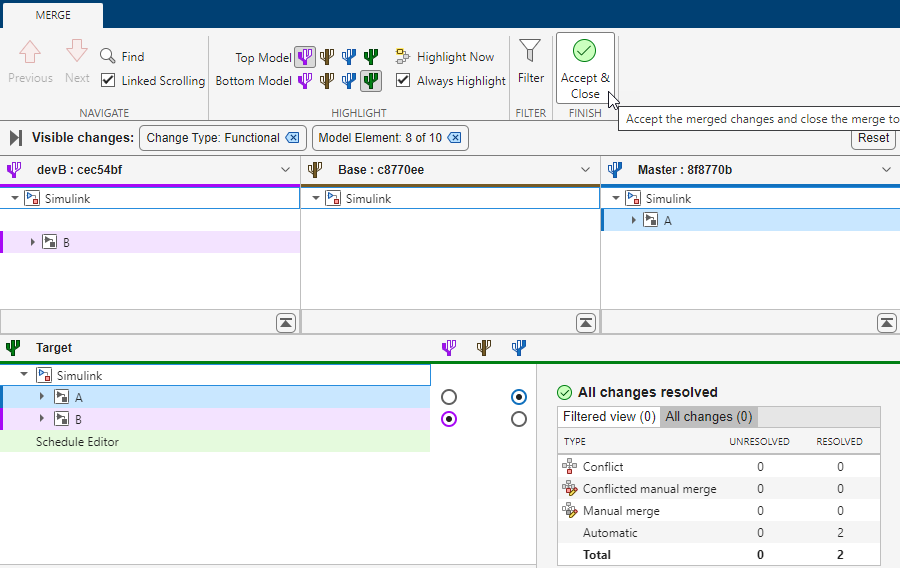

The changes have been merged and are now ready to commit.

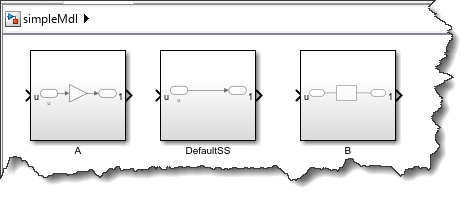

## Now it's your turn

Are you having success merging Simulink models? Let us know in the comments below.